**Dataset Import and initial analysis**

clc
clear all

%load the data
data = readtable("MSFT_2006-01-01_to_2018-01-01.csv");
data

data = 3019×7 table
       Date       Open     High      Low     Close      Volume        Name  
    __________    _____    _____    _____    _____    __________    ________

    2006-01-03    26.25       27     26.1    26.84    7.9974e+07    {'MSFT'}
    2006-01-04    26.77    27.08    26.77    26.97    5.7976e+07    {'MSFT'}
    2006-01-05    26.96    27.13    26.91    26.99    4.8248e+07    {'MSFT'}
    2006-01-06    26.89       27    26.49    26.91    1.0097e+08    {'MSFT'}
    2006-01-09    26.93    27.07    26.76    26.86    5.5628e+07    {'MSFT'}
    2006-01-10    26.65    27.02    26.59       27    6.4925e+07    {'MSFT'}
    2006-01-11    27.01    27.39     26.9    27.29    7.0124e+07    {'MSFT'}
    2006-01-12    27.25    27.26    26.97    27.

%Removing the last column since it is a constant with value "MSFT"
data(:,end) = [];

%Look for missing values
missingvalues = sum(ismissing(data))

missingvalues =      0     0     0     0     0     0


%% Find range of data according to data
dateRange = [min(data.Date) max(data.Date)]

dateRange = 1×2 datetime array
   2006-01-03   2017-12-29


%Make "close" the last variable since it is the response 
closingPrice = data.Close;
data(:,"Close") = [];
data.Close = closingPrice;

%Summary of the dataset
summary(data)

Variables:

    Date: 3019×1 datetime

        Values:

            Min       2006-01-03
            Median    2011-12-30
            Max       2017-12-29

    Open: 3019×1 double

        Values:

            Min         15.2  
            Median     29.99  
            Max        87.12  

    High: 3019×1 double

        Values:

            Min        15.62  
            Median     30.23  
            Max         87.5  

    Low: 3019×1 double

        Values:

            Min        14.87  
            Median     29.78  
            Max        86.23  

    Volume: 3019×1 double

        Values:

            Min       7.4256e+06
            Median    4.6175e+07
            Max       5.9108e+08

    Close: 3019×1 double

        Values:

            Min        15.15  
            Median        30  
            Max        86.85  



**Data Visualization**

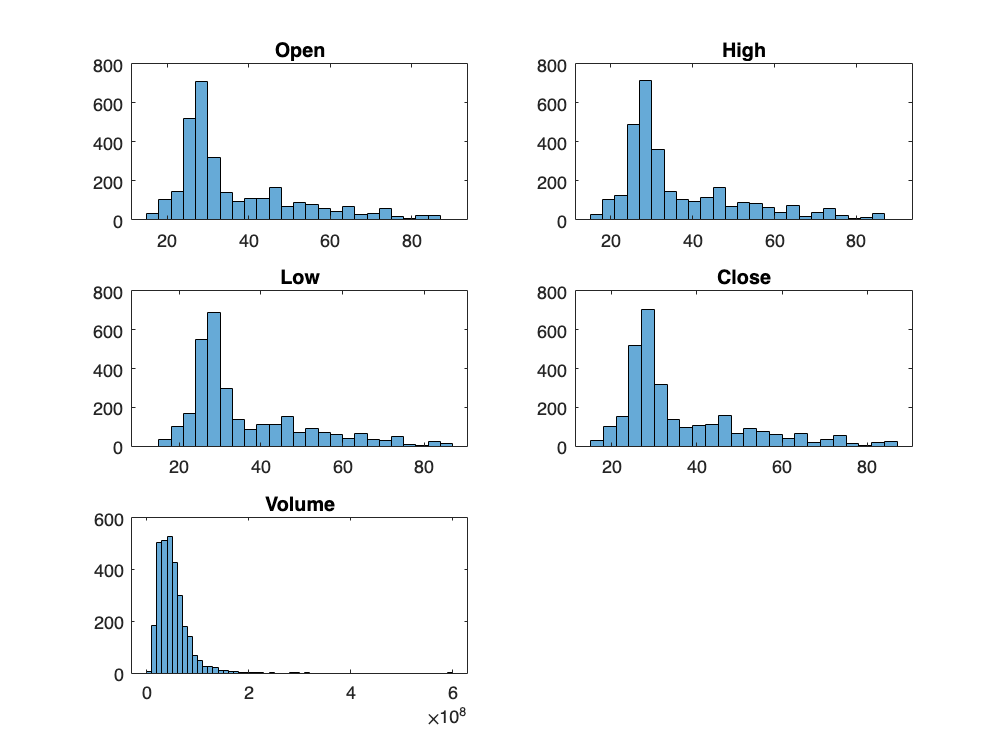

%Convert the data table to matrix
stocks = table2array(data(:,["Open","High","Low","Close","Volume"]));
% keep date in a seperate datetime variable
dateVar = table2array(data(:,"Date"));

columnNames = ["Open","High","Low","Close","Volume"];

%Histograms
figure
for i = 1:5
    subplot(3,2,i)
    histogram(stocks(:,i))
    title(columnNames(i))
end

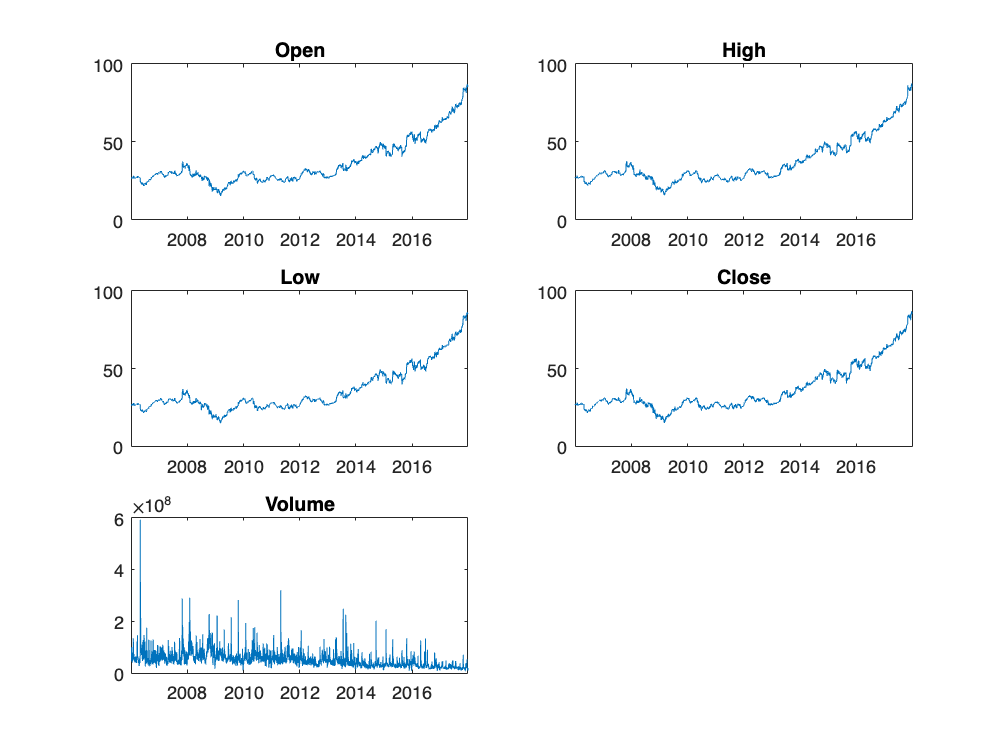

%Time series analysis of each variable
figure
for i = 1:5
    subplot(3,2,i)
    plot(dateVar,stocks(:,i))
    title(columnNames(i))
end

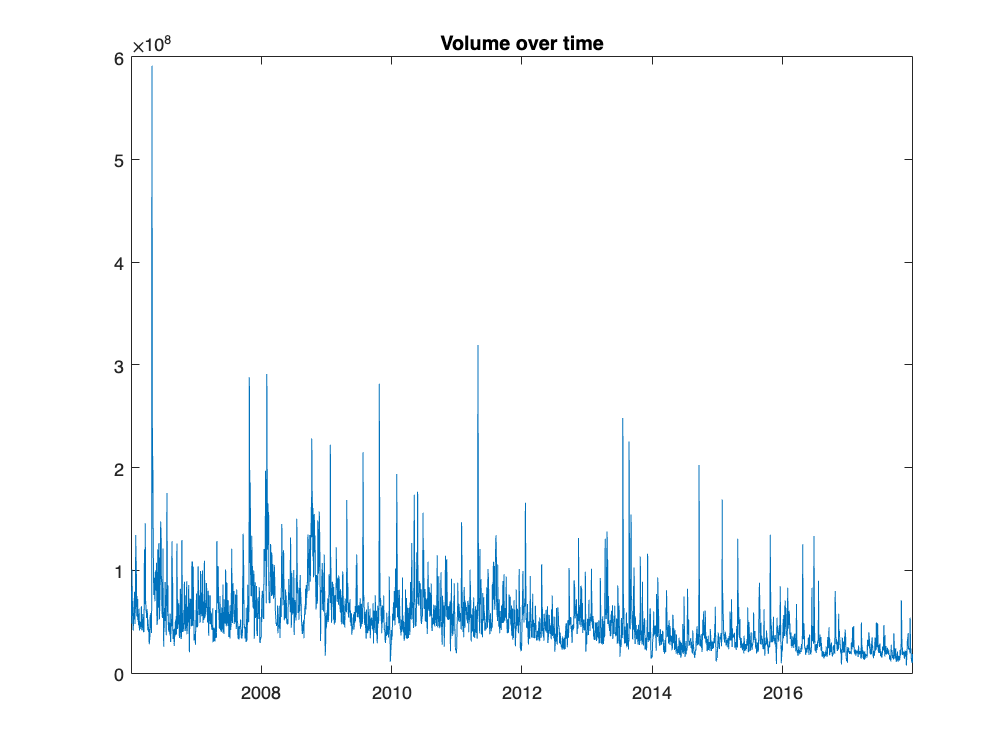

%Volume may be showing some seasonality over time. Lets take a look at it
figure
plot(dateVar,stocks(:,end))
title("Volume over time")

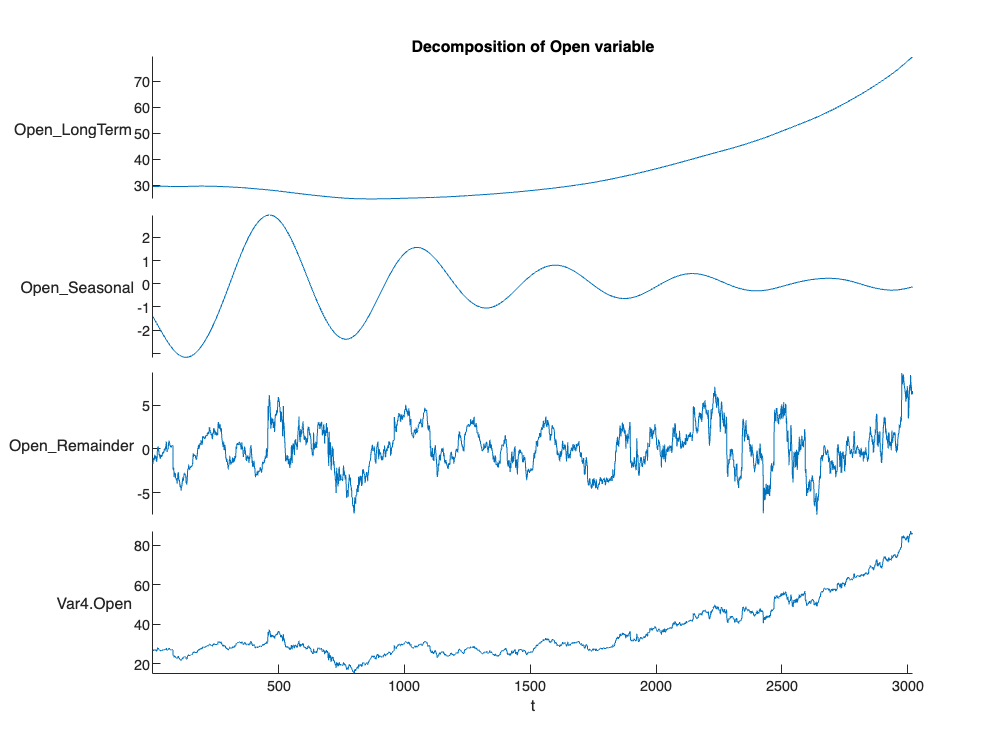

%Trend decomposition

%Open
D = trenddecomp(data(:,"Open"));
D = addvars(D,data(:,"Open"));
stackedplot(D)
xlabel("t")
title("Decomposition of Open variable") 